# **Part 1 of System Identification Exercise List 1**

**Due by September 19, 2026**

**Name:**

**Student ID (I):**

clear all
I=5;% número do grupo

**Questão 1 **-  Seja  um motor cc  com tensão nominal de 30 V, mostrado na Figura  abaixo:

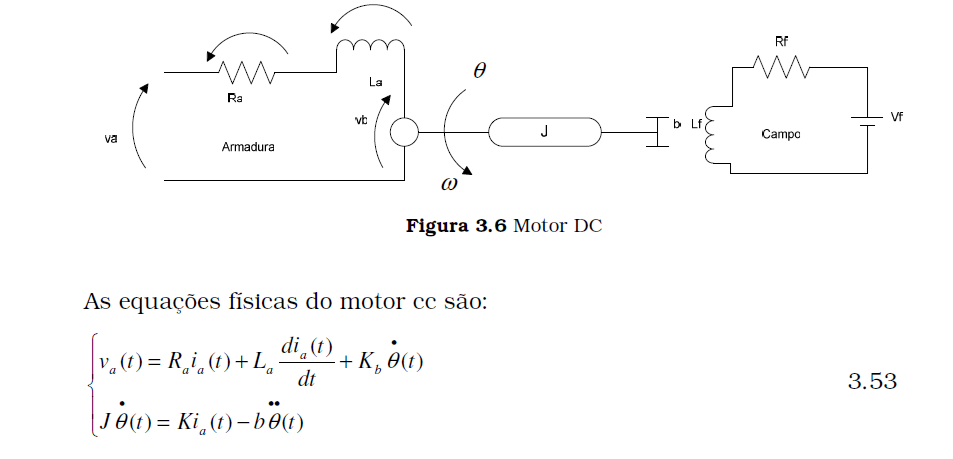

onde $R_a$ e $L_a$ são a resistencia e  a indutância da armadura, $k_b$ é a cte da fcem, $J$ é a inécia da carga ,  $K, b$ são constantes de elasticidade e do atrito do eixo do motor com a carga. Os parâmetros nominais do motor cc são gerados a seguir:

[dados]=dadosmotor(I);
%% resistência armadura, indutancia armadura, cte fcem, inercia, cte elasticidade, atrito



As equações   de  estado e  de saída deste sistema são: 

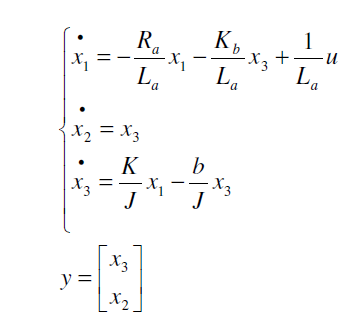

onde u é a tensão de entrada, $x_1=i_a, x_2=\theta, x_3=\frac{d \theta}{dt}$. O código a seguir gera as matrizes Ad,Bd, Cd, e Dd da eq. de estado discreta do motor cc:

ra=dados(1);
la=dados(2);
kb=dados(3);
jm=dados(4);
k=dados(5);
b=dados(6);
Ts=0.01; %periodo de amostragem
A=[-ra/la 0 -kb/la; 0 0 1;k/jm 0 -b/jm];
B=[1/la;0;0];
C=[0 0 1];
D=[0];
SYSC=ss(A,B,C,D);
SYSd=c2d(SYSC,Ts,'zoh');
Ad=SYSd.A;
Bd=SYSd.B;
Cd=SYSd.C;
Dd=SYSd.D;


1.1  Simule este sistema à entrada degrau de 10 V, e obtenha as FTs relacionando a velocidade angular com a tensão de entrada ($G_3(s)= \frac{X_3(s)}{U(s)$),  e a posição angular com a tensão de entrada ($G_2(s)=\frac{X_2(s)}{U(s)}$).

1.2 Obtenha:

i) A  função de transferência discreta de $G_3(s)$, supondo o período de amostragem de Ts seg e assumindo o segurador de ordem zero;

ii) A  função de transferência discreta de $G_2(s)=\frac{X_2(s)}{U(s)}$, supondo o período de amostragem de Ts seg e assumindo o segurador de ordem zero;

ii) As representações dos processos ARX de velocidade e posição em termos da equação a diferenças (os polinômios A(z) e B(z)) .

1.3 Compare as respostas ao degrau da FT discreta $G_3(s)= \frac{X_3(s)}{U(s)$ com a obtida na simulação do item 1.1. 

2  -   Gere uma entrada binária aleatória  usuando o código abaixo. Forneça um período de amostragem menor ou igual a  1 segundo e um tempo final maior ou igual a 100 segundos

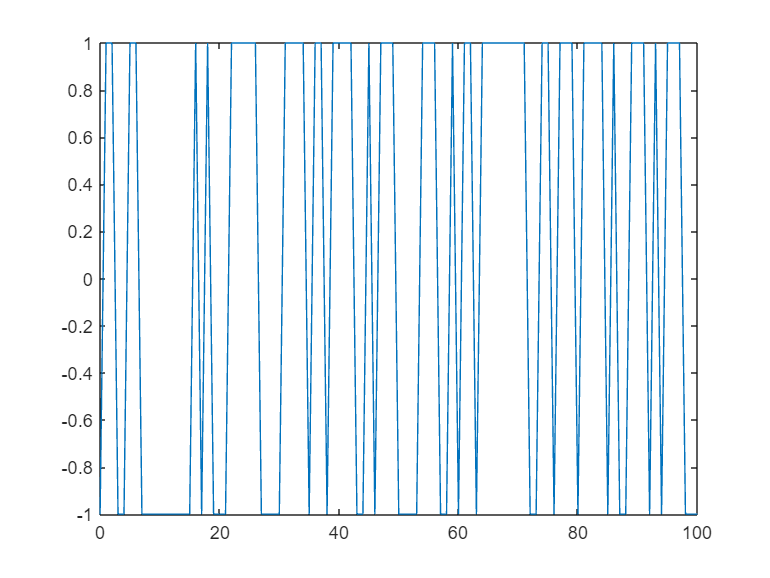


% Seqüência binária aleatória
delta=1; %período de amostragem
tf=100; % tempo final
t=[0:delta:tf];sna=rand(size(t));l=0;
while l==0
alfa=0.5;
if alfa<=1
if alfa>=0
l=1;
end
end
if l==0
disp('Alfa deve estar entre 0 e 1');
end
end
for i=1:length(t),
if sna(i)<=alfa,sbpa(i)=-1;
else sbpa(i)=1;
end
end
plot(t,sbpa);

2.1 Usando o sinal PRBS gerado pelo código acima na entrada do motor descrito na questão 1, obtenha a resposta ao impulso da velocidade do motor, através do método de convolução (conforme exemplo 3.5.1 pg. 162 do livro do Aguirre, 3ª edição). Analise  os seguintes casos:

i)  Sem ruído de medição

ii)  Considere que na velocidade do motor há um ruído branco gaussiano com média zero e desvio padrão igual a $10^{-2}$.

Compare as respostas ao impulso calculadas nestes dois  casos  com a resposta ao impulso do motor.

2.2  Usando o sinal PRBS gerado pelo código acima na entrada do motor descrito na questão 1, obtenha a resposta em frequência da velocidade do motor  usando as transformadas de Fourier dos sinais de entrada e de saída (conforme exemplo 3.6.2 pg. 167 do livro do Aguirre, 3ª edição).Analise  os seguintes casos:

i)  Sem ruído de medição

ii)  Considere que na velocidade do motor há um ruído branco gaussiano com média zero e desvio padrão igual a $10^{-2}$.

Compare as respostas em frequência  calculadas nestes dois  casos  com a resposta em frequência do motor.